## Buck Boost

% Parametros de projeto
Vs = 30;
Vo = 20;
fs = 40 * 1e3;
P = 15;
delta_Vo = 0.1;
delta_Il = 0.3;
T = 1/fs;

% Calculo do duty cycle
aux = (Vo/Vs);
D = aux / (1 + aux)

D = 0.4000


% Carga 
R = (Vo^2)/P 

R = 26.6667


% Corrente média no indutor
iL = Vo / (R * (1 - D))

iL = 1.2500


% Corrente max e min no indutor
iL_min = iL - ((delta_Il * iL)/2)

iL_min = 1.0625

iL_max = iL + ((delta_Il * iL)/2)

iL_max = 1.4375


% iL RMS
delta_iL = iL_max - iL_min;
iL_rms = sqrt(iL^2 + (delta_iL^2)/12)

iL_rms = 1.2547


% Calculo do indutor
L = (Vs * D * T) / (delta_Il * iL)

L = 8.0000e-04


% Calculo do capacitor
C = (Vo * D) / (delta_Vo * Vo * R * fs)

C = 3.7500e-06


% Indutancia mininima para CCM
Lmin = (((1-D)^2)*R)/(2*fs)

Lmin = 1.2000e-04


if L > Lmin
    disp("L > Lmin: opera em CCM")
else
    disp("L < Lmin: nao opera em CCM")
end

L > Lmin: opera em CCM


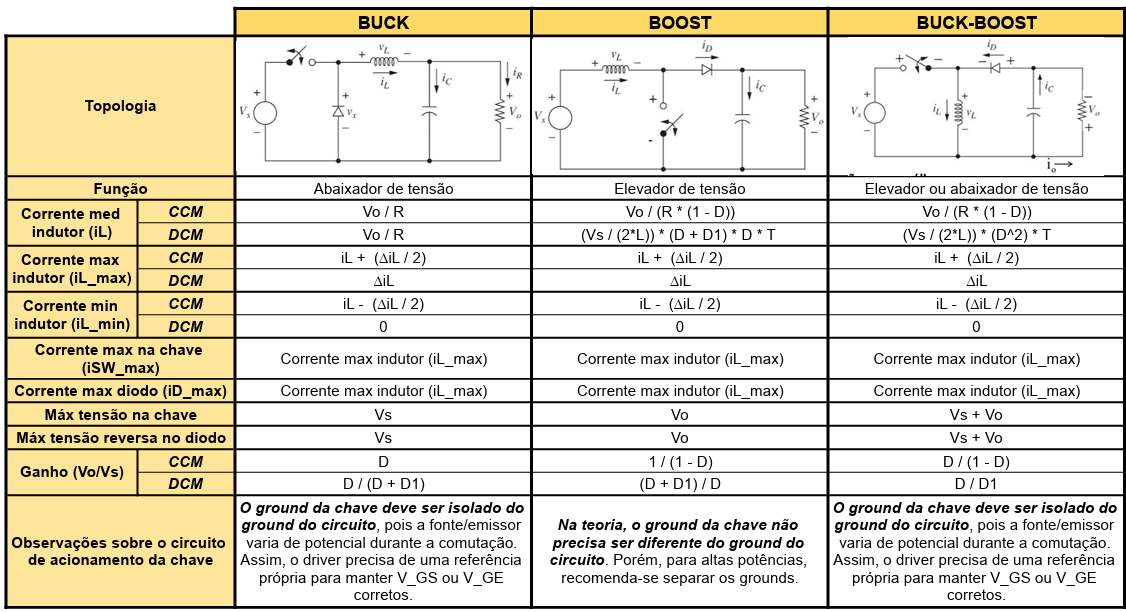

max_V_chave = Vs + Vo

max_V_chave = 50

max_i_chave = iL_max

max_i_chave = 1.4375

max_V_diodo = Vs + Vo

max_V_diodo = 50

max_i_diodo = iL_max

max_i_diodo = 1.4375

## Acionamento MOSFET

% Parametros de projeto
